## **制御シミュレーションのチュートリアル**

このチュートリアルは，マス・ばね・ダンパ系の簡単なシミュレーションをすることで制御シミュレーションの流れをつかんでもらうことを目的としています．

### マス・ばね・ダンパ系のモデル

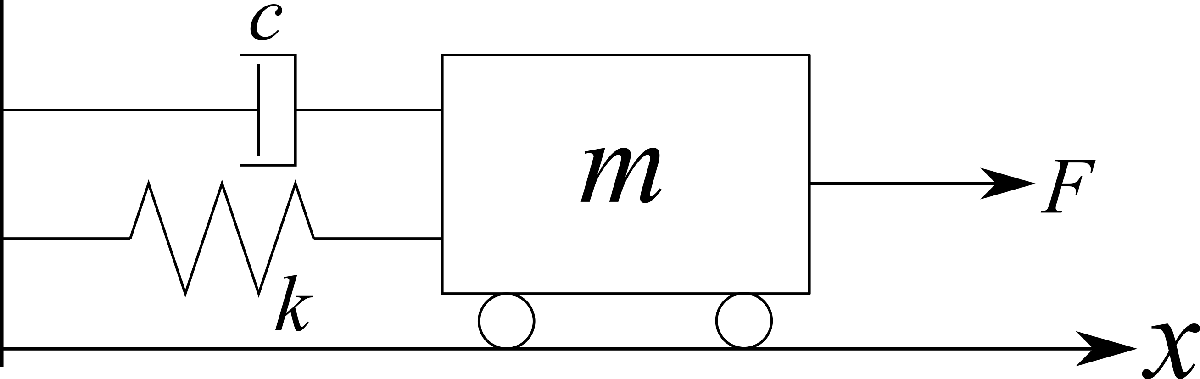

図 1  マス・ばね・ダンパ系のモデル

図 1 に示すマス・ばね・ダンパ系の，台車の変位と速度の時間応答のシミュレーションを行います．

まずシミュレーションをするために，図 1 に示す台車のモデルを数式で表しましょう．この台車のモデルは，まず台車の運動方程式をたて，それを式変形することで作ります．台車の運動方程式を以下に示します．

## 
$$m\ddot{x}(t) + c\dot{x}(t) + kx(t) = F$$


ここで，$m，c，k，t，x，F$はそれぞれ台車の質量，減衰係数，ばね定数，時間，$x$方向の変位，外力です．下のセルにマス・ばね・ダンパ系のパラメータを設定するコードを打ち込みます．

m = 1    % 質量[kg]
k = 1    % ばね定数[N/m]
c = 0.2  % 減衰係数[N s/m]

この運動方程式を$\dot{x} = Ax + Bu$のような形に変形します．制御の世界ではこれを動特性と呼び，台車のモデルを表しています．動特性は台車の動き方であり，台車の初期値が分かれば台車の次の状態を求めていけるようになります．

今，外力は制御入力のみで与えられる$(F = u)$とし，ヒントを以下に示すので自分で係数$A，B$を求めてみてください．

ヒント

- $x_1(t) = x(t)，x_2(t) = \dot{x}(t)$とおく．

- $\dot{\mathit{\mathbf{x}}} \left(t\right)$$= \left[
                \begin{array}{rrr}
                   \dot{x_1}(t) \\
                   \dot{x_2}(t)
                \end{array}
               \right]$とする．　（$\dot{\mathit{\mathbf{x}}} \left(t\right)$と$\dot{x}(t)$は別変数）

$A，B$が求まったら下のセルに打ち込んでください．パラメータの値は代入せず，文字のままで打ち込んでください．

A =         % 2行2列の行列

式が無効です。不足している文字または余分な文字をチェックしてください。

B =         % 2行1列の行列

### 制御入力がない場合のシミュレーション

求めた動特性を使ってシミュレーションを行っていきます．まずは外力がない状態$F = u = 0$の場合を考えていきましょう．

シミュレーションは台車の状態を微小時間だけ次の状態へ更新し，それを繰り返すことで行います．まずは1つ先のステップの状態$x$を求めてみましょう．今回，$x$の更新の仕方はオイラー法を用います．式を以下に示します．

## 
$$x_{after} = x_{before} + dt ・\dot{x}$$


u = 0    % 入力なし
dt = 0.1    % 刻み幅
x1 = -5    % 台車の位置の初期値
x2 = 0    % 台車の速度の初期値
x = [x1 ; x2]    % 台車の状態


x_dot =         % 動特性
x = x +         % オイラー法

これで1つ先のステップが求められました．後はこれを繰り返せば，未来の台車の状態が求まります．ただし，上の3行のコードをfor文で囲うだけでは，グラフにしようとしたとき過去の計算結果が消えてしまいます．1ステップごとの計算結果はどこかに保存しておかなければなりません．よって次のセルに計算結果を保存するためのコードを説明します．

x_h = []    % 計算結果を保存するための箱を準備
x_h = [x_h x];    % 箱に計算結果を収納していく

以上のことを使って，図2に示すマス・ばね・ダンパ系のシミュレーションを行い，時間と変位の関係をグラフにしましょう．

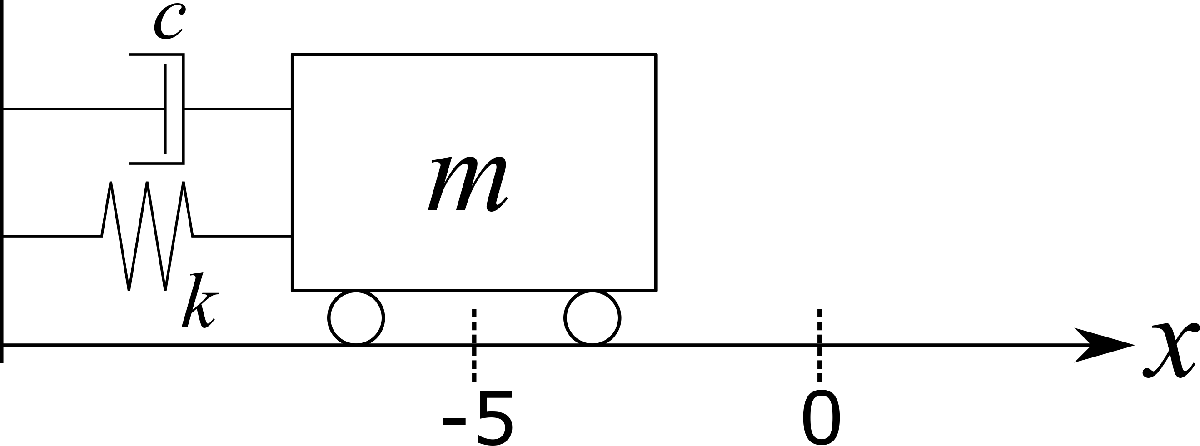

図2　マス・ばね・ダンパ系（x1 = -5）

下のセルに台車の初期値とシミュレーションを行うための初期値は打ち込んでおきます．反復回数はどれくらい先のステップまで計算するかであり，刻み幅は微小時間のことです．for文の中をうめてください．※for文の中に書くコードは後ろに；をつけてください（何もつけないとステップごとに計算結果がすべて表示されてしまうため，それを防ぐ）

x1 = -5    % 変位[m]
x2 = 0    % 速度[m/s]
x = [x1 ; x2]    % 状態
t = 0    % 初期時間[s]
Ns = 1000    % 反復回数
dt = 0.1    % 刻み幅[s]
u = 0    % 入力

for i = 1 : Ns
    
    
    
    
    
    
    
    
    
    
end


%----計算結果をグラフで表示する----%
% 横軸に時間，縦軸に台車の変位でプロットする
plot(t_h, x_h(1,:))
% x_h(1,:)はx_hの1行目を抽出するという意味

筆者が同じ初期値でシミュレーションを行った結果を以下の図に示します．

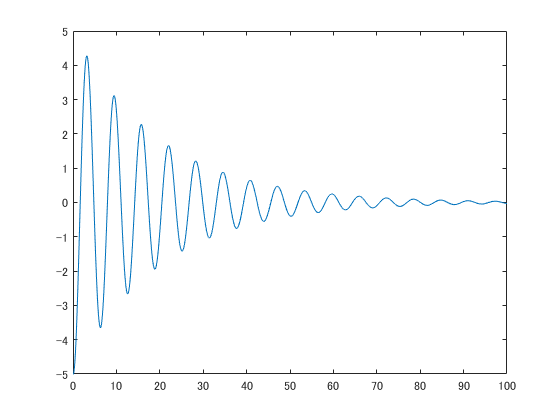

### 制御入力がある場合のシミュレーション

次に，制御入力を付加して台車の変位を目標値へ制御するシミュレーションを行いましょう．制御入力は以下の式で与えます．

## 
$$u = K_p e(t) + K_i \int_0^t e(\tau)d\tau + K_d \frac{d}{dt} e(t)$$


## 
$$e(t) = r - x(t)$$


ここで，$e(t)$は目標値$r$と現在値との偏差，$K_p，K_i，K_d$はそれぞれゲインです．

この式はPID制御と呼ばれ，制御で広く用いられる式です．この式の説明を軽くすると，第一項目は比例項(Proportional)，第二項目は積分項(Integral)，第三項目は微分項(Differential)になっています．

比例項の部分は目標値と離れているときは大きな入力を与え，目標値に近づいてきたらゆっくりと調整します．しかし，比例項のみだと目標値付近で振動したり，収束先が目標値と離れた値（定常偏差）をとってしまうことがあります．定常偏差の例を図3に示します．

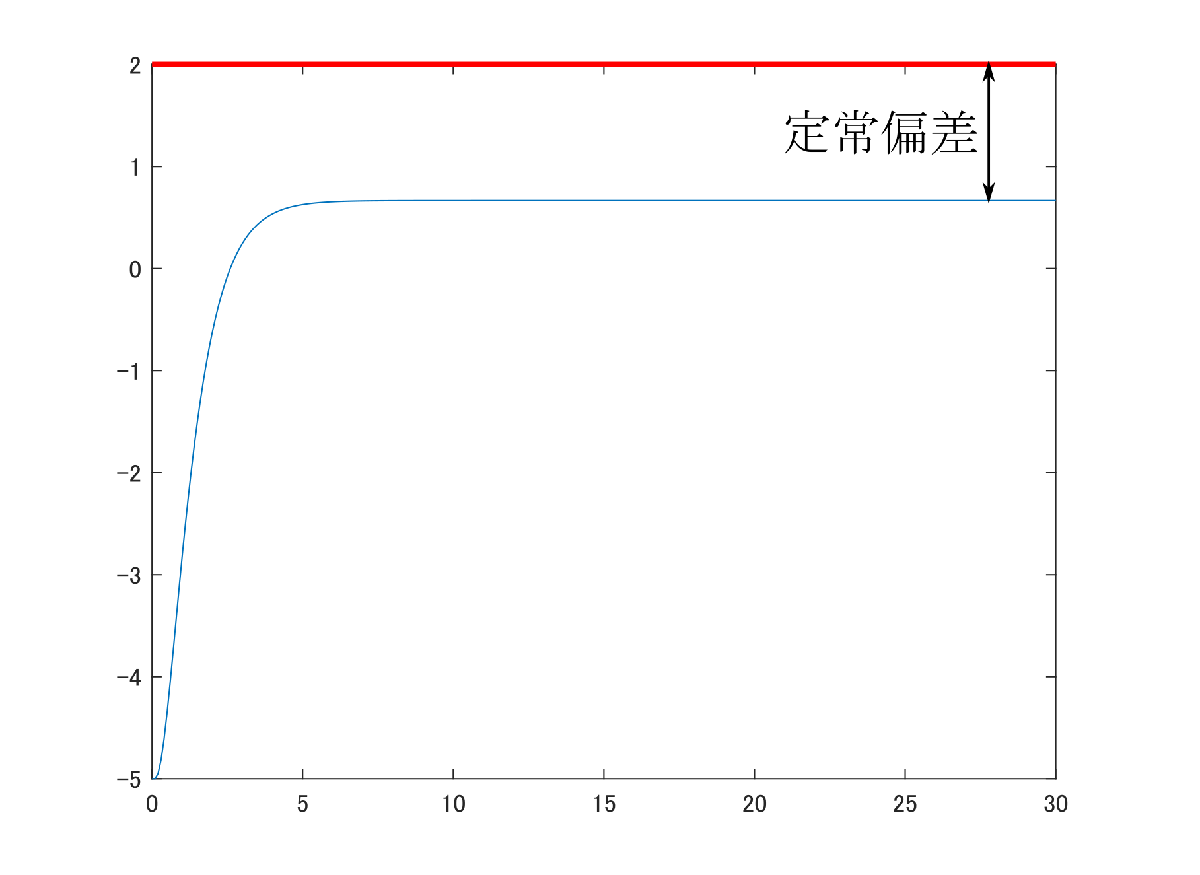

図3　定常偏差

これらを改善するために，積分項と微分項を導入します．

例えば図4のような結果が得られたとします．

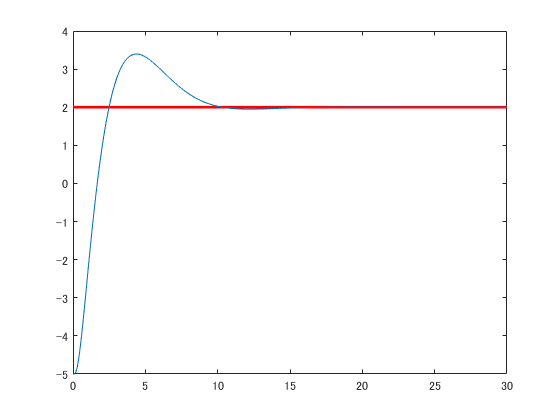

図4　積分項の説明（1）

ここで，青線が得られた結果で，赤線が目標値です．

このとき，積分項の偏差の積分とは青線と赤線で囲まれた空間になります．この空間をピンク色で塗ったものを図5に示します．

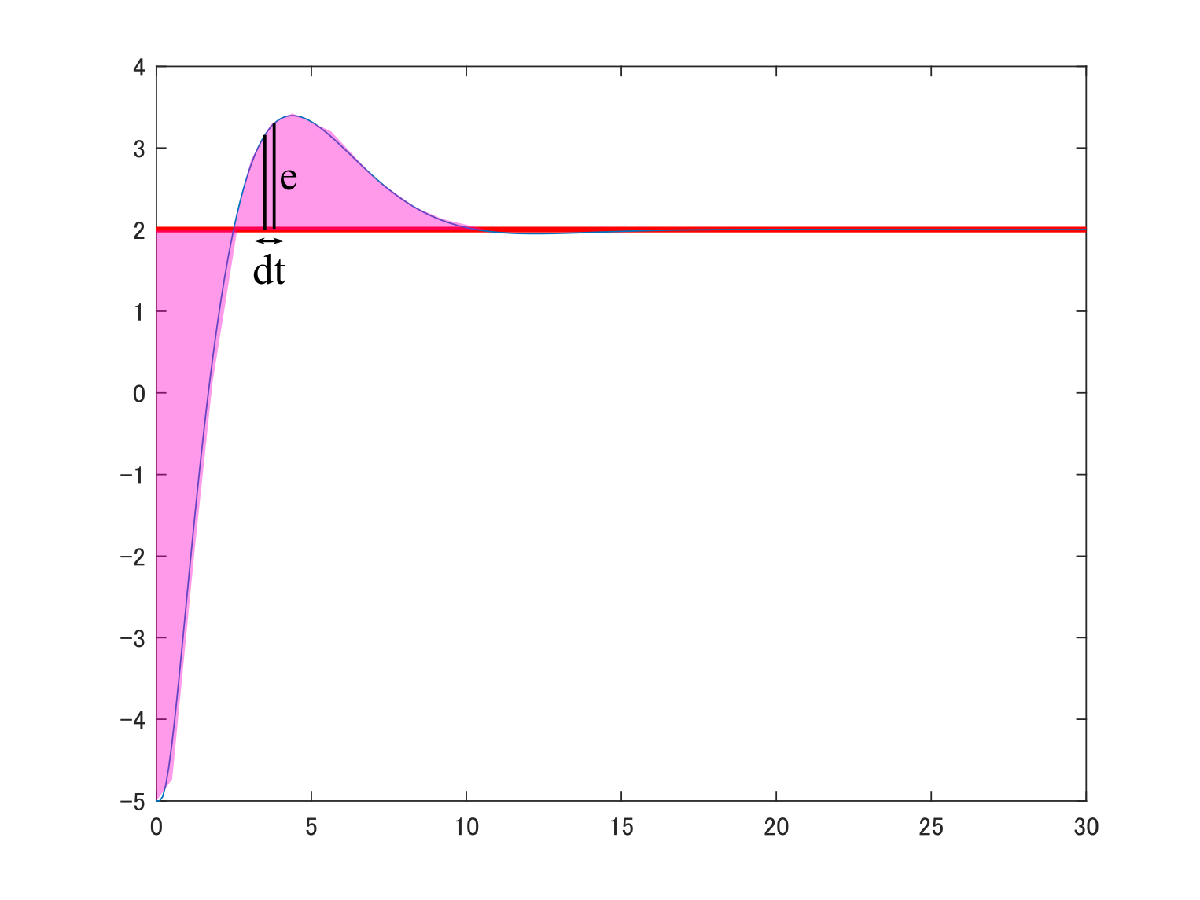

図5　積分項の説明（2）

この「誤差の累積」を入力に含めれば誤差をけせるのでは？と考えたのが積分項になります．積分項を加えることで，定常偏差を0にすることができます．

微分項は偏差の勢いを表しています．この微分項は目標値に近づいてきたらブレーキをかけるような役割を持っています．例えば図4のグラフはオーバーシュート（目標値を行き過ぎる）が起きていることがわかります．微分項をうまく調整すると図6のようにオーバーシュートを消すことができます．

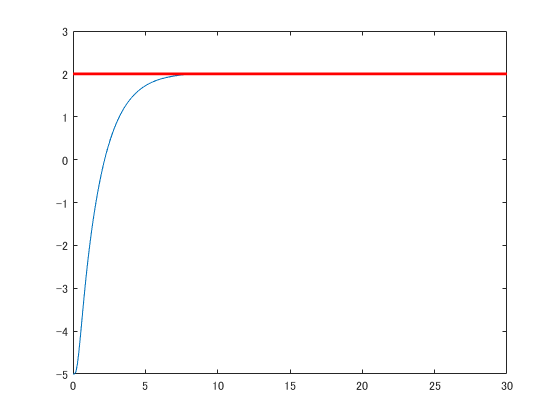

図6　微分項の調整

以上がPID制御の説明になります．このPID制御をマス・ばね・ダンパ系に導入していきましょう．

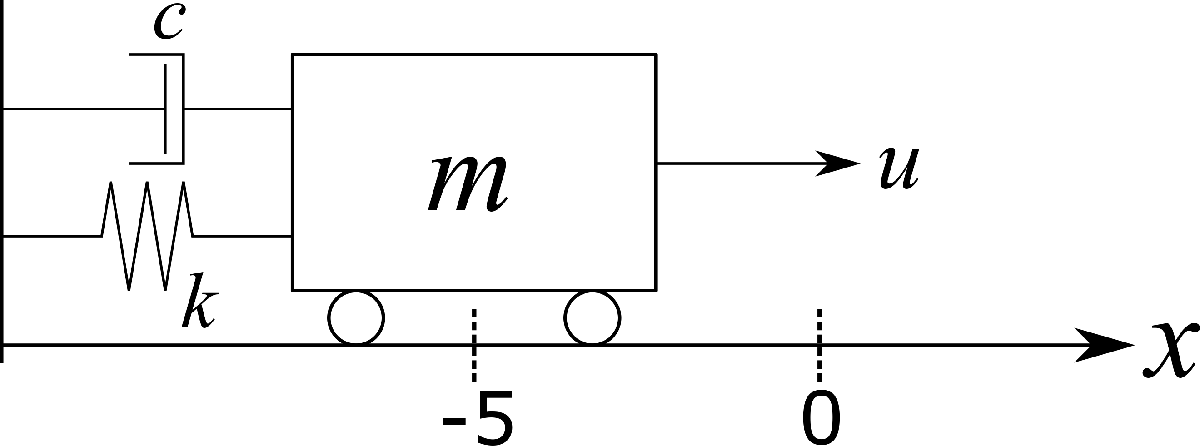

図7　マス・ばね・ダンパ系（制御あり）

図7に示すマス・ばね・ダンパ系のシミュレーションを行います．

制御ありのシミュレーションは制御なしの場合とほとんど変わりません．制御入力があるだけです．今までの知識を用いてシミュレーションを行い，台車の変位と時間のグラフをだしてください．台車の初期位置などは筆者が下のセルに打ち込んだので（ゲインは筆者が適当に決めた），PID制御をどう実装するかを自分で考えてみてください．※for文の中に書くコードは後ろに；をつけてください（何もつけないとステップごとに計算結果がすべて表示されてしまうため，それを防ぐ）

ヒントを以下に示します．

ヒント

- 積分は足し合わせで表現できる

- 微分は現在の値と1つ前の値の差で表現できる

x1 = -5    % 変位[m]
x2 = 0    % 速度[m/s]
x = [x1 ; x2]    % 状態
t = 0    % 初期時間[s]
Ns = 1000    % 反復回数
dt = 0.1    % 刻み幅[s]
Kp = 0.5    % 比例ゲイン
Ki = 0.5    % 積分ゲイン
Kd = 2    % 微分ゲイン
r = 2    % 目標値


for i = 1 : Ns
    
    
    
    
    
    
    
    
    
    
    
    
    
end


%----計算結果をグラフで表示する----%
% 横軸に時間，縦軸に台車の変位でプロットする
plot(t_h, x_h(1,:))

筆者が同じ初期値でシミュレーションを行った結果を以下の図に示します．

オーバーシュートが起こっているのでゲインの調整を各自してみてください．

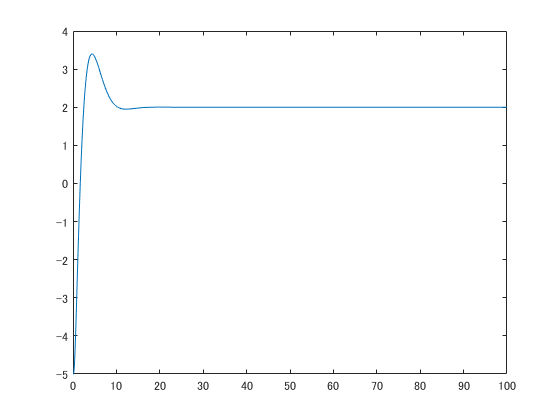

## グラフの編集方法について

今まで，グラフはデフォルトのままでしか表示させてきませんでしたが，線の色を変えたり，太さを変えたり，ラベルを貼ったりなど，matlabはグラフを色々編集できます．その例をいくつか示すので，下のセルに制御ありのシミュレーション結果を編集してみてください．

例

- plot(t_h, x_h(1,:), '-r')  ：　赤色の実線に変更

- plot(t_h, x_h(1,:), 'LineWidth', 3)　：　線の太さを3ptに変更

- plot(t_h, x_h(1,:), '.')　：　グラフを点でプロットする

- xlim([0 50])　：　x軸の範囲を指定

- `xlabel('time[s]', 'FontSize', 12)　：　x軸のラベルを指定（フォントサイズは12pt）`

- `grid on　：　グリッド線の追加`

% この下にグラフの編集コードを書いてください












今回紹介したもの以外にもいろいろ編集コマンドはあるので，各自必要に応じて調べてください．

### 最後に

制御シミュレーションのチュートリアルにお付き合いいただきありがとうございました．これからマス・ばね・ダンパ系の制御よりも難しい問題に向き合わなければいけないと思いますが，めげずに頑張ってください．研究生活が楽しいものになることを願っています．

付録

付録として筆者が書いたコードを示します．今までの問題の参考例になっているので，コードの書き方など参考にしてください．また，subplotを使ってグラフを複数表示させたので，subplotの使い方の参考になるかもしれません．

以下，筆者のGitHubのページの/IMC2019/mass_spring/からmass_spring_tutorial.mをおとしてきてください．GitHubからのおとしかたは先生か院生にきいてください．

[https://github.com/kt4km/IMC2019](https://github.com/kt4km/IMC2019)

Gitの使い方のリンクを以下に示します．

[http://172.24.137.242:8823/git_intro.html](http://172.24.137.242:8823/git_intro.html)